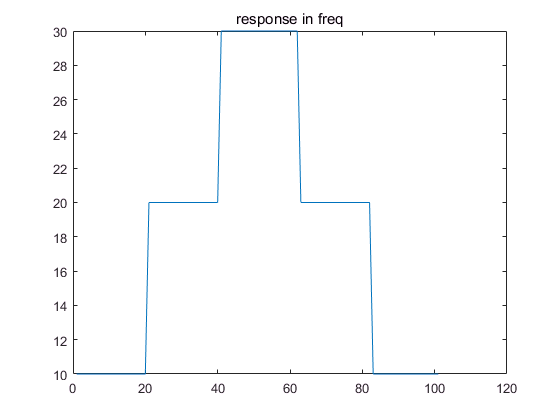

N = 101;

M = (N + 1) / 2;

responseDB = ones(1, N);
index = 1;
while index <= M
    responseDB(index) = fix((index - 1)/ 20 + 1) * 10;
    index = index + 1;
end

for i = 1 : (N - M)
    responseDB(M + i) = responseDB(M - i + 1);
end

plot(responseDB);
title('response in freq')

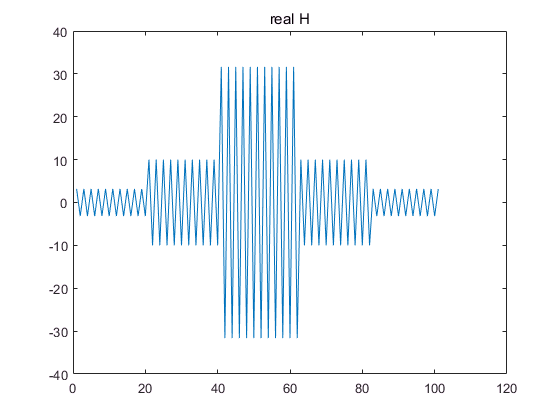


response = power(10, responseDB .* 0.05);
%response = responseDB;


w0 = 2 * pi / N;
theta = (w0 * 1) .* [0 : 1 : N - 1];
phase = exp(-1i .* theta);

H = response .* phase;

plot(real(H));
title('real H');

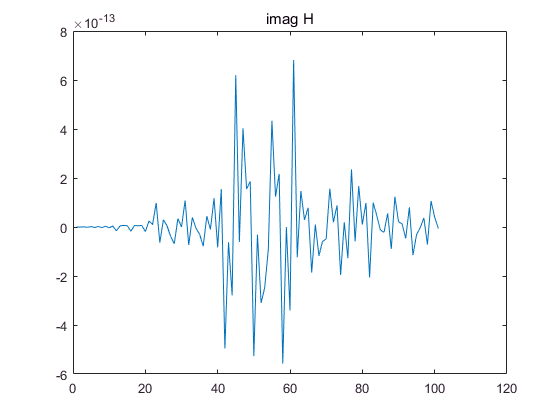


plot(imag(H));
title('imag H');


h = ifft(H)

h =    0.0313 + 0.0000i   0.0313 + 0.1979i   0.0313 - 0.1676i   0.0313 + 0.1551i   0.0313 - 0.1564i   0.0313 - 0.0796i   0.0313 + 0.2309i   0.0313 - 0.1698i   0.0313 + 0.1325i   0.0313 - 0.1069i   0.0313 - 0.1595i   0.0313 + 0.2545i   0.0313 - 0.1612i   0.0313 + 0.0995i   0.0313 - 0.0494i   0.0313 - 0.2403i   0.0313 + 0.2673i   0.0313 - 0.1407i   0.0313 + 0.0550i   0.0313 + 0.0167i   0.0313 - 0.3233i   0.0313 + 0.2669i   0.0313 - 0.1061i   0.0313 - 0.0033i   0.0313 + 0.0937i   0.0313 - 0.4111i   0.0313 + 0.2495i   0.0313 - 0.0532i   0.0313 - 0.0803i   0.0313 + 0.1864i   0.0313 - 0.5095i   0.0313 + 0.2073i   0.0313 + 0.0270i   0.0313 - 0.1875i   0.0313 + 0.3073i   0.0313 - 0.6329i   0.0313 + 0.1223i   0.0313 + 0.1576i   0.0313 - 0.3556i   0.0313 + 0.4917i   0.0313 - 0.8239i   0.0313 - 0.0613i   0.0313 + 0.4166i   0.0313 - 0.7000i   0.0313 + 0.8868i   0.0313 - 1.2820i   0.0313 - 0.6472i   0.0313 + 1.3319i   0.0313 - 2.2644i   0.0313 + 3.6137i   0.0313 -10.2084i   0.0313 +10.2084i   0.031

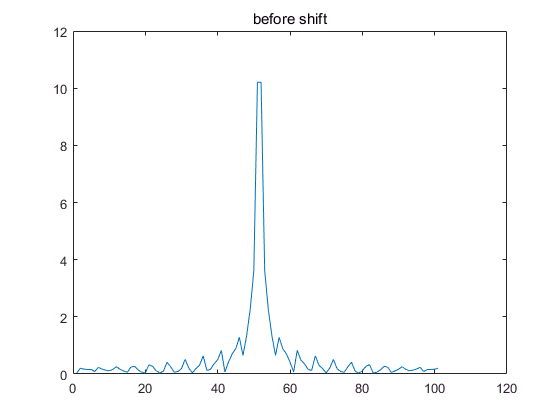


plot(abs(h))
title('before shift')

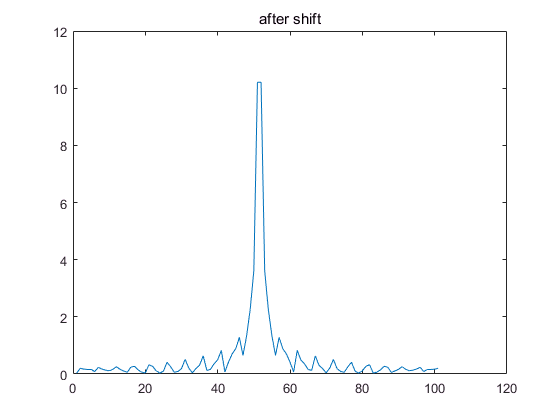


h = circshift(h',M)'



plot(abs(h));
title('after shift')

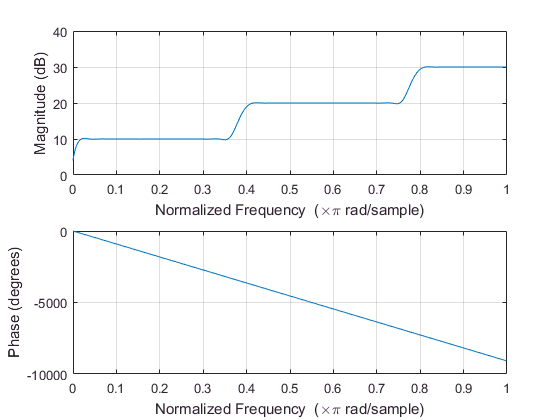

window = hanning(N);

h = h .* window';
freqz(h);